f=@(x) sin(pi/2*x) + 1/2*x.^2 - x

f = function_handle with value:
    @(x)sin(pi/2*x)+1/2*x.^2-x


fd=@(x) pi/2*cos(pi/2*x) + x - 1

fd = function_handle with value:
    @(x)pi/2*cos(pi/2*x)+x-1



x=0:4;
y=f(x);
yd=fd(x);

A=[0,  0, 0, 1,  0,  0, 0;
   1,  1, 1, 1,  0,  0, 0;
   8,  4, 2, 1,  1,  0, 0;
  27,  9, 3, 1,  8,  1, 0;
  64, 16, 4, 1, 27,  8, 1;
   0,  0, 1, 0,  0,  0, 0;
  48,  8, 1, 0, 27, 12, 3];
b=[0,1/2,0,1/2,4,fd(0),fd(4)]';

c=A\b;
p=c(1:4);

xx=linspace(0,4,100);
yy=f(xx);
yyd=fd(xx);

pp=polyval(p,xx);
bb1=max(xx-1,0).^3;
bb2=max(xx-2,0).^3;
bb3=max(xx-3,0).^3;

ss=pp+c(5)*bb1+c(6)*bb2+c(7)*bb3;

pd=[3*p(1),2*p(2),p(3)]';
ppd=polyval(pd,xx);
bbd1=max(xx-1,0).^2;
bbd2=max(xx-2,0).^2;
bbd3=max(xx-3,0).^2;

ssd=ppd+3*c(5)*bbd1+3*c(6)*bbd2+3*c(7)*bbd3;

subplot(2,1,1)
plot(x,y,'k*', xx,yy, 'b-', xx,ss, 'r-')
legend('pontok','fv','spline')
title('Függvény közelítése spline-nal')
hiba=max(abs(yy-ss));
disp(hiba)

    0.0236



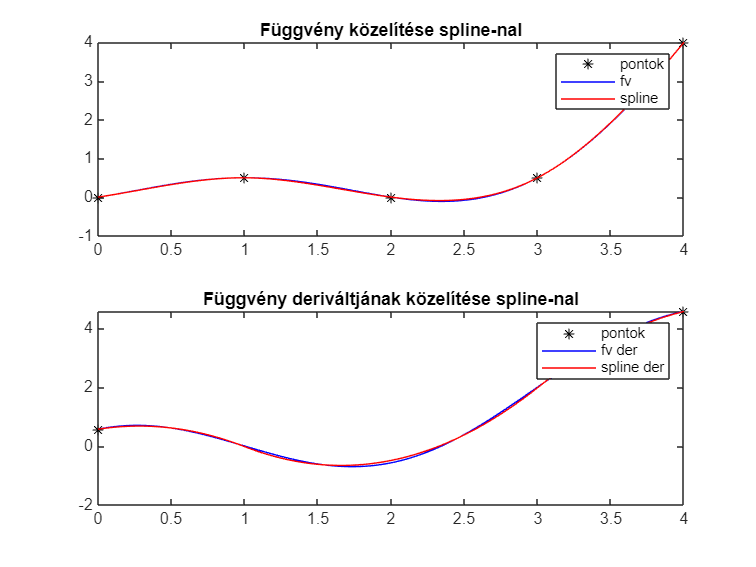


subplot(2,1,2)
plot([0,4],[fd(0),fd(4)],'k*',xx,yyd,'b-',xx,ssd,'r-')
legend('pontok','fv der','spline der')
title('Függvény deriváltjának közelítése spline-nal')